clear; clc;

% From 1-1.5 wing box taper is modified to reduce NC
modL= 2.786/2+ 0.2

modL =    1.593000000000000


boxW_root= 1.9;
boxH_mod = (4.027 - 0.1713.*modL) * (0.0989+0.0879)/2;
boxW_mod = (4.027 - 0.1713.*modL) * (0.6-0.15)

boxW_mod =    1.689353595000000


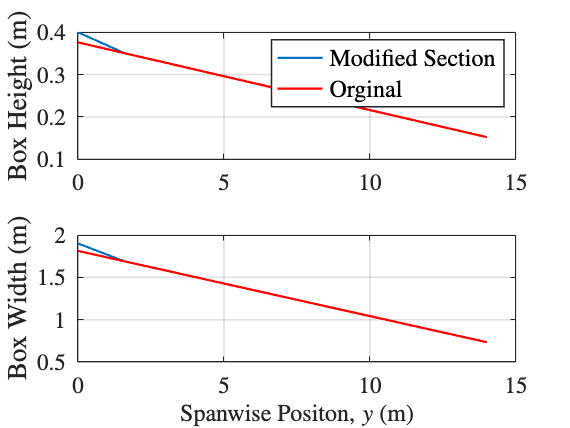

boxH_root = 0.4;
mMod = (boxH_root - boxH_mod) / -modL;
mModW = (boxW_root - boxW_mod) / -modL;

yInner = 0:0.01:modL;
boxH_inner = boxH_root + mMod * yInner;
boxW_inner = boxW_root + mModW * yInner;

yOut = 0:0.1:14;
chord = (4.027 - 0.1713.*yOut);
box_height = chord.*(0.0989+0.0879)/2;
box_width = (0.6-0.15).*chord;

figure
subplot(2,1,1)
plot(yInner, boxH_inner,'b-','LineWidth',1.5)
hold on
plot(yOut, box_height,'-','Color','r','LineWidth',1.5)
hold off
grid on
box on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Box Height (m)', 'Interpreter','latex', 'FontSize',18)
legend('Modified Section','Orginal', 'Interpreter','latex', 'FontSize',16)

subplot(2,1,2)
plot(yInner, boxW_inner,'b-','LineWidth',1.5)
hold on
plot(yOut, box_width,'-','Color','r','LineWidth',1.5)
hold off
grid on
box on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Box Width (m)', 'Interpreter','latex', 'FontSize',18)
xlabel('Spanwise Positon, $y$ (m)', 'Interpreter','latex', 'FontSize',18)


%saveas(gcf,'wingBoxMods.png')